## Heat Conduction in Cylindrical Coordinates with 2 Flux BCs

clear


#### Set up the differential shell balance

#### 0=$\frac{\left(2\pi \textrm{rL}q_r \right)|_{r+\Delta r} -\left(2\pi \textrm{rL}q_r \right)|_r }{2\pi \textrm{Lr}\Delta r}$

syms q(r) T(r) k r L dr R1 R2  h1 h2 T1 T2 C1 C2
assume(R1,'real')
assumeAlso(R1,'positive')
assume(R2,'real')
assumeAlso(R2,'positive')

difq(r) = ((2*pi*(r+dr)*L*q(r+dr))-2*pi*r*L*q(r))/(2*pi*r*L*dr)

$$difq(r) = -\frac{2\,\pi \,L\,r\,q\left(r\right)-2\,\pi \,L\,q\left(\mathrm{dr}+r\right)\,\left(\mathrm{dr}+r\right)}{2\,L\,\mathrm{dr}\,r\,\pi }$$

#### Take the limit as the shell volume shrinks to zero 

0=$\lim_{\Delta r\to 0} \frac{\left(2\pi \textrm{rL}q_r \right)|_{r+\Delta r} -\left(2\pi \textrm{rL}q_r \right)|_r }{2\pi \textrm{Lr}\Delta r}$

qEqn(r) = limit(difq(r), dr, 0) ==0

$$qEqn(r) = \frac{r\,q^{\prime }\left(r\right)+q\left(r\right)}{r}=0$$

#### Solve the ODE for q(r)

q(r) = dsolve(qEqn)

$$q(r) = \frac{C_{1}}{r}$$

### Use Fourier's Law to find T(r)

TEqn = k*diff(T) == q(r)

$$TEqn(r) = k\,\frac{\partial }{\partial r}T\left(r\right)=\frac{C_{1}}{r}$$

### Solve the ODE to find T(r)

T(r) = dsolve( TEqn)

$$T(r) = C_{2}+\frac{C_{1}\,\log\left(r\right)}{k}$$

### Apply Newton's Law of Cooling at both Boundaries

BC1 = q(R1) == h1*(T1-T(R1))

$$BC1 = \frac{C_{1}}{R_{1}}=-h_{1}\,\left(C_{2}-T_{1}+\frac{C_{1}\,\log\left(R_{1}\right)}{k}\right)$$

BC2 = q(R2) == h2*(T(R2)-T2)

$$BC2 = \frac{C_{1}}{R_{2}}=h_{2}\,\left(C_{2}-T_{2}+\frac{C_{1}\,\log\left(R_{2}\right)}{k}\right)$$

### Solve for the Constants of Integration

[C1sol, C2sol] = solve ([BC1 BC2],[C1 C2]);
C1sol = simplifyFraction(C1sol, "Expand",true)

$$C1sol = \frac{R_{1}\,R_{2}\,T_{1}\,h_{1}\,h_{2}\,k-R_{1}\,R_{2}\,T_{2}\,h_{1}\,h_{2}\,k}{R_{1}\,h_{1}\,k+R_{2}\,h_{2}\,k+R_{1}\,R_{2}\,h_{1}\,h_{2}\,\log\left(R_{1}\right)-R_{1}\,R_{2}\,h_{1}\,h_{2}\,\log\left(R_{2}\right)}$$

C1sol=simplify(C1sol)

$$C1sol = \frac{R_{1}\,R_{2}\,h_{1}\,h_{2}\,k\,\left(T_{1}-T_{2}\right)}{R_{1}\,h_{1}\,k+R_{2}\,h_{2}\,k+R_{1}\,R_{2}\,h_{1}\,h_{2}\,\log\left(R_{1}\right)-R_{1}\,R_{2}\,h_{1}\,h_{2}\,\log\left(R_{2}\right)}$$

[n,d]=numden(C1sol)

$$n = R_{1}\,R_{2}\,h_{1}\,h_{2}\,k\,\left(T_{1}-T_{2}\right)$$

$$d = R_{1}\,h_{1}\,k+R_{2}\,h_{2}\,k+R_{1}\,R_{2}\,h_{1}\,h_{2}\,\log\left(R_{1}\right)-R_{1}\,R_{2}\,h_{1}\,h_{2}\,\log\left(R_{2}\right)$$

numerator_factors=factor(n)

$$numerator\_factors = \left(\begin{array}{cccccc} R_{1} & R_{2} & h_{1} & h_{2} & k & T_{1}-T_{2} \end{array}\right)$$

nsimp= n/(R1*R2*h1*h2*k)

$$nsimp = T_{1}-T_{2}$$

dsimp=simplify(d/(R1*R2*h1*h2*k))

$$dsimp = \frac{R_{1}\,h_{1}\,k+R_{2}\,h_{2}\,k+R_{1}\,R_{2}\,h_{1}\,h_{2}\,\log\left(R_{1}\right)-R_{1}\,R_{2}\,h_{1}\,h_{2}\,\log\left(R_{2}\right)}{R_{1}\,R_{2}\,h_{1}\,h_{2}\,k}$$

dsimp=simplify(expand(dsimp))

$$dsimp = \frac{1}{R_{1}\,h_{1}}+\frac{1}{R_{2}\,h_{2}}+\frac{\log\left(\frac{R_{1}}{R_{2}}\right)}{k}$$


C1sol=simplify(nsimp/dsimp, 'IgnoreAnalyticConstraints',true)

$$C1sol = \frac{T_{1}-T_{2}}{\frac{1}{R_{1}\,h_{1}}+\frac{1}{R_{2}\,h_{2}}+\frac{\log\left(\frac{R_{1}}{R_{2}}\right)}{k}}$$

While correct, this much more complicated than one would get solving "longhand" to get a form that leads to the overall heat transfer coefficient as the inverse sum of three (reciprocal) resistances - same issue with C2sol:


$$C_1 =\frac{T_1 -T_2 }{\frac{1}{R_1 h_1 }+\frac{\ln \left(\frac{R_1 }{R_2 }\right)}{k}+\frac{1}{R_2 h_2 }}$$


C2sol = simplify(C2sol, "Steps", 1000)

$$C2sol = \frac{R_{1}\,T_{1}\,h_{1}\,k+R_{2}\,T_{2}\,h_{2}\,k-R_{1}\,R_{2}\,T_{1}\,h_{1}\,h_{2}\,\log\left(R_{2}\right)+R_{1}\,R_{2}\,T_{2}\,h_{1}\,h_{2}\,\log\left(R_{1}\right)}{R_{1}\,h_{1}\,k+R_{2}\,h_{2}\,k+R_{1}\,R_{2}\,h_{1}\,h_{2}\,\log\left(\frac{R_{1}}{R_{2}}\right)}$$

### Substitute the constants into the expression for T(r)

T(r) = subs(T(r), [C1 C2], [C1sol C2sol]);
T(r) = simplify(T,"Steps",1000)

$$T(r) = \frac{R_{1}\,T_{1}\,h_{1}\,k+R_{2}\,T_{2}\,h_{2}\,k+R_{1}\,R_{2}\,T_{1}\,h_{1}\,h_{2}\,\log\left(r\right)-R_{1}\,R_{2}\,T_{2}\,h_{1}\,h_{2}\,\log\left(r\right)-R_{1}\,R_{2}\,T_{1}\,h_{1}\,h_{2}\,\log\left(R_{2}\right)+R_{1}\,R_{2}\,T_{2}\,h_{1}\,h_{2}\,\log\left(R_{1}\right)}{R_{1}\,h_{1}\,k+R_{2}\,h_{2}\,k+R_{1}\,R_{2}\,h_{1}\,h_{2}\,\log\left(\frac{R_{1}}{R_{2}}\right)}$$

# How can I simplify to collect terms like this -even 10000 Steps doesn't pull together lna-lnb=lna/b or cancel common terms in numerator and denominator?  Also, the reslult seems incorrect.  Term in the numerator should be R2h2log(R1), not log(R2). 


$$T\left(r\right)=T_2 +\frac{\left(\ln \left(\frac{r}{R_1 }\right)+\frac{k}{h_1 R_1 }\right)\left(T_1 -T_2 \right)}{\left(\frac{k}{h_1 R_1 }+\ln \left(\frac{R_2 }{R_1 }\right)+\frac{k}{h_2 R_2 }\right)}$$


### Define Dimensionless Variables

$\hat{T} \equiv \frac{T\left(r\right)-T_2 }{T_1 -T_2 }$  and $\hat{r} \equiv \frac{r}{R_1 }$

syms That rhat
T(rhat)=subs(T(r), r, R1*rhat);
T = simplify(T, "Steps",1000)

$$T(rhat) = \frac{R_{1}\,T_{1}\,h_{1}\,k+R_{2}\,T_{2}\,h_{2}\,k+R_{1}\,R_{2}\,T_{1}\,h_{1}\,h_{2}\,\log\left(\mathrm{rhat}\right)-R_{1}\,R_{2}\,T_{2}\,h_{1}\,h_{2}\,\log\left(\mathrm{rhat}\right)+R_{1}\,R_{2}\,T_{1}\,h_{1}\,h_{2}\,\log\left(\frac{R_{1}}{R_{2}}\right)}{R_{1}\,h_{1}\,k+R_{2}\,h_{2}\,k+R_{1}\,R_{2}\,h_{1}\,h_{2}\,\log\left(\frac{R_{1}}{R_{2}}\right)}$$

That(rhat) = (T(rhat)-T2)/(T1-T2);
That = simplify(That, "Steps", 1000)

$$That(rhat) = 1-\frac{R_{2}\,h_{2}\,k-R_{1}\,R_{2}\,h_{1}\,h_{2}\,\log\left(\mathrm{rhat}\right)}{R_{1}\,h_{1}\,k+R_{2}\,h_{2}\,k+R_{1}\,R_{2}\,h_{1}\,h_{2}\,\log\left(\frac{R_{1}}{R_{2}}\right)}$$

### Insert Dimensionless Numbers

syms Bi1 Bi2
% Bi1 = h1*R1/k
That = subs(That, [h1 h2], [k*Bi1/R1 k*Bi2/R2]);
%Bi2 = h2*R2/k
That = simplify(That, "Steps", 1000)

$$That(rhat) = \frac{{\mathrm{Bi}}_{2}\,\left({\mathrm{Bi}}_{1}\,\log\left(\mathrm{rhat}\right)-1\right)}{{\mathrm{Bi}}_{1}+{\mathrm{Bi}}_{2}+{\mathrm{Bi}}_{1}\,{\mathrm{Bi}}_{2}\,\log\left(\frac{R_{1}}{R_{2}}\right)}+1$$

### Substitute dimensionless expressions

# *How do I get to this form?  Since expression above seems wrong, I am manually redefining That*

### 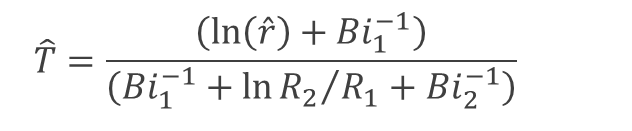

# *Assuming the substitutions work I should have gotten - BTW is it possible to get symbols with speial characters like "circimflex hat" or vetor bar?*

That =(log(rhat)+1/Bi1)/(1/Bi1+log(R2/R1)+1/Bi2)

$$That = \frac{\log\left(\mathrm{rhat}\right)+\frac{1}{{\mathrm{Bi}}_{1}}}{\log\left(\frac{R_{2}}{R_{1}}\right)+\frac{1}{{\mathrm{Bi}}_{1}}+\frac{1}{{\mathrm{Bi}}_{2}}}$$

#### *Change form of dimensionless radius to unify plots of differing aspect ratio to all go - [0:1]*

syms rstar
ThatNew = subs(That,rhat,(rstar*((R2/R1)-1)+1))

$$ThatNew = \frac{\log\left(\mathrm{rstar}\,\left(\frac{R_{2}}{R_{1}}-1\right)+1\right)+\frac{1}{{\mathrm{Bi}}_{1}}}{\log\left(\frac{R_{2}}{R_{1}}\right)+\frac{1}{{\mathrm{Bi}}_{1}}+\frac{1}{{\mathrm{Bi}}_{2}}}$$

#### *Plot the effect of Bi for R2/R1 = 2*

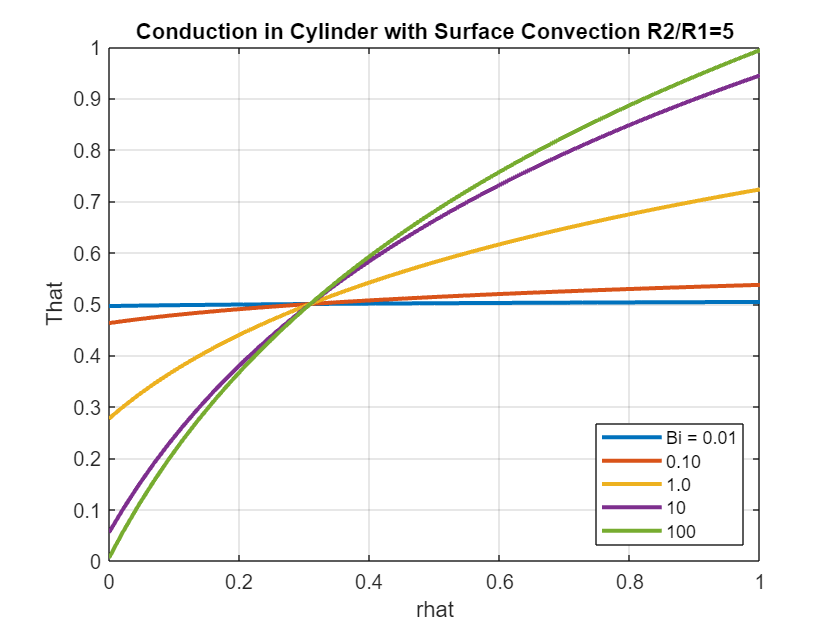

ThatNew2 = subs(ThatNew, [R2 Bi2], [5*R1 Bi1]);


for i=-2:2
    ThatPlot = subs(ThatNew2, 'Bi1', 10^i);
    fplot(ThatPlot, [0 1],'Linewidth',2)
    hold on
end

xlabel('rhat')
ylabel('That')
title('Conduction in Cylinder with Surface Convection R2/R1=5')
legend("Bi = 0.01", "0.10", "1.0", "10", "100", 'Location','southeast')
grid on
hold off

#### (Equivalent Plot from Excel)

                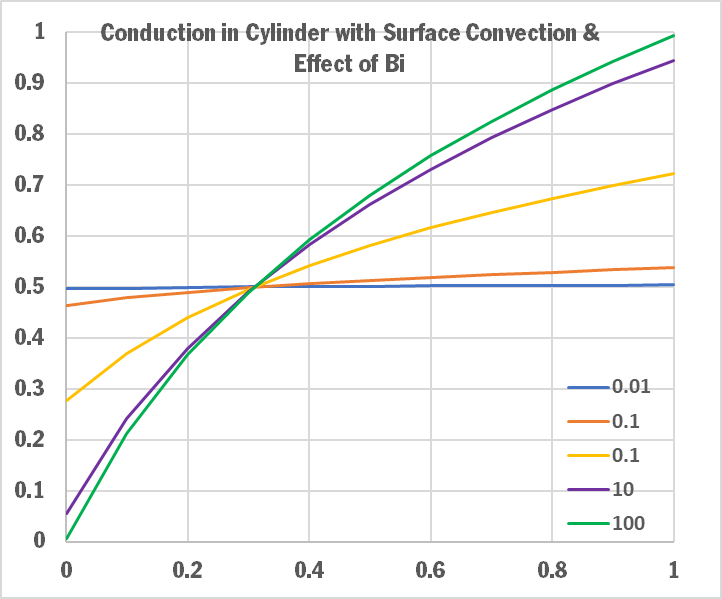

ThatNew2 = subs(ThatNew, [Bi1 Bi2 R1], [100 100 1])

$$ThatNew2 = \frac{\log\left(\mathrm{rstar}\,\left(R_{2}-1\right)+1\right)+\frac{1}{100}}{\log\left(R_{2}\right)+\frac{1}{50}}$$

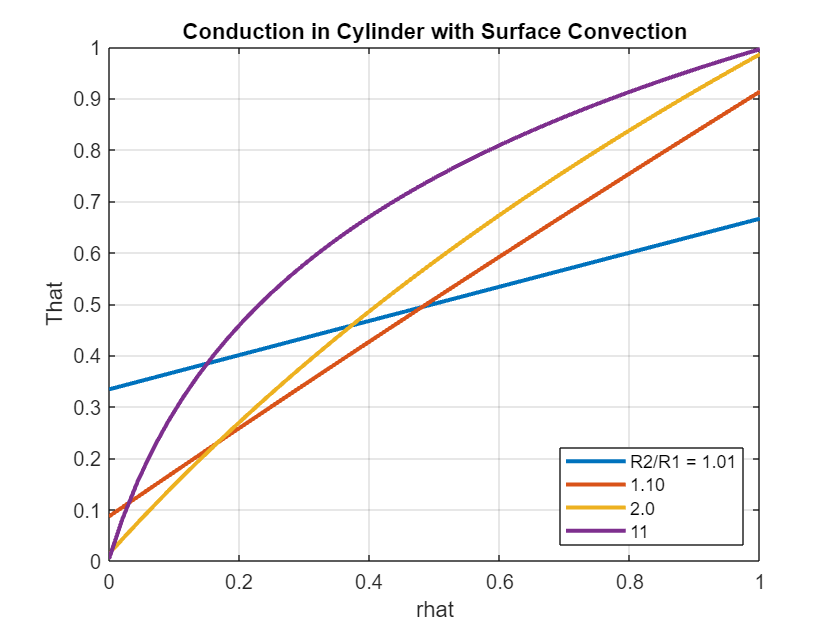

for i=-2:1
    ThatPlot = subs(ThatNew2, 'R2', 1+10^i);
    fplot(ThatPlot, [0 1],'Linewidth',2)
    hold on
end
xlabel('rhat')
ylabel('That')
title('Conduction in Cylinder with Surface Convection')
legend("R2/R1 = 1.01", "1.10", "2.0", "11", 'Location','southeast')
grid on
hold off

#### (Equivalent Plot from Excel)

## 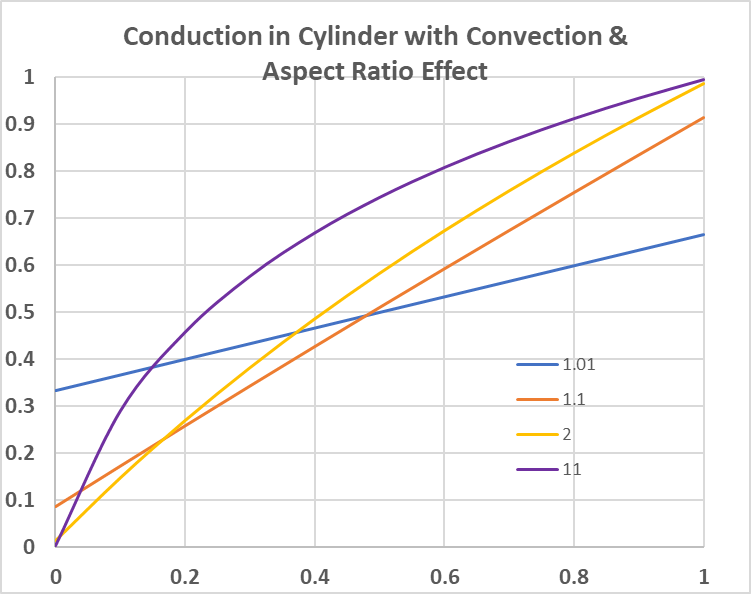

## Calculate Heat Loss

clear Q L theta z
syms Q L theta z

Q = R2*int(int(q(R2), theta,[0 2*pi]), z, [0 L])

$$Q = 2\,\pi \,C_{1}\,L$$

Q = subs(Q, C1, C1sol);
Q = simplify(expand(Q),"Steps",1000)

$$Q = \frac{2\,\pi \,L\,R_{1}\,R_{2}\,h_{1}\,h_{2}\,k\,\left(T_{1}-T_{2}\right)}{R_{1}\,h_{1}\,k+R_{2}\,h_{2}\,k+R_{1}\,R_{2}\,h_{1}\,h_{2}\,\log\left(\frac{R_{1}}{R_{2}}\right)}$$

# *What I want is to simplify to:*

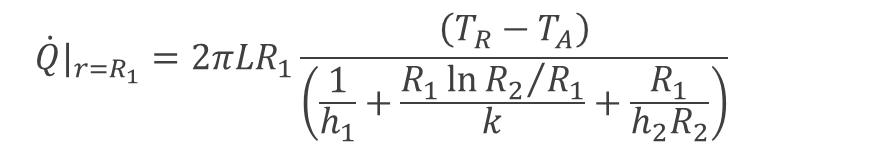

# *So I can define the overall heat transfer coefficient, Uov*

$U_{\textrm{OV}} ={\left(\frac{1}{h_1 R_1 }+\frac{\ln \left(\frac{R_2 }{R_1 }\right)}{k}+\frac{1}{h_2 R_2 }\right)}^{-1}$  with  $A_W =2{\pi R}_1 L$ $ $

# *Therefore:*


$$\dot{Q} =U_{\textrm{OV}} A_W \left(T_2 -T_1 \right)$$
